# **Acute Inflammations **SVM Classifier

## Samuel Ndirangu 

Github: [https://github.com/SamNdirangu/](https://github.com/SamNdirangu/)

LinkedIn: [https://www.linkedin.com/in/samndirangu](https://www.linkedin.com/in/samndirangu)

Date: 29/04/2019

**Introduction**

This data was created to aid development of an algorithm which will perform the presumptive diagnosis of two diseases of urinary system. It features 120 samples each with 5 features that are used to diagnose two conditions at the same time. Of each of the 2 conditions there are 2 classes representing whether having the disease or not

**References and Dataset source ** 

J.Czerniak, H.Zarzycki (2009). UCI Machine Learning Repository [ [http://archive.ics.uci.edu/ml/datasets/acute+inflammation](http://archive.ics.uci.edu/ml/datasets/acute+inflammation) ]. Irvine, CA: University of California, School of Information and Computer Science. 

## Step 1: Dataset Preparation

Here we prepare our data so that it can be fed to the svm accordingly.

The data is first loaded from an excel xlsx file and the necessry collumns extracted.

The data is then split into training-validation and tests sets. One trains the svm the other is used to evaluate its practical accuracy perfomance.

The data is also shuffled up so as to avoid any variance or bias problems that may arise.

## File Upload

%Stores our file name and path
[file,path] = uigetfile({'*.xlsx';'*.csv'},'Select Data File')

file = 'aci.xlsx'

path = 'C:\Users\Mheshimiwa\ML Projects\Acute Inflammations\'

selectedfile = fullfile(path,file);

opts = detectImportOptions(selectedfile); %Auto Load options for it
temp_data = readtable(selectedfile,opts); %Read the xlsx file and store it.

data = table2cell(temp_data); %Convert our table to a cell array for ease of access

%Get our feature names
data_feature_names = cellstr(strrep(temp_data.Properties.VariableNames,'_',' '));
sample_no = size(data,1) %Get the number of all diagnosis

sample_no = 120

%Create our X and Y for SVM Training
rand_num = randperm(sample_no); % Permutate numbers upto 569 randomly, This works as shuffling our rows

%Load our X with features
%After several attempts the best prediction so far were achieved using 7 of the 9 features
X_temp = cell2mat(data(:,1));
for count=2:6
    X_temp(:,count) = grp2idx(data(:,count));
end
X = X_temp(rand_num(1:end),:);

Y_temp = data(:,7:8);
Y = Y_temp(rand_num(1:end),1); %True Diagnosis of the first disease: Inflammation of the bladder
Y2 = Y_temp(rand_num(1:end),2); %True Diagnosis of the second disease: Nephritis

## Step 2: Perform Cross Validation  : K-fold 5

To reduce any underfitting or overfitting that may occur during testing the data is cross validated using K-Fold 10 times. The folds are stratified ensuring a uniform distribution of each class with in each fold further lowering any data bias that would have been present.

%Validate now the training set using Kfold 10 times
aci_CV = cvpartition(Y,'KFold',5,'Stratify',true);

## Step 3: Train a SVM and Evaluate Validation Loss : Kernel linear

This step will now train the SVM using the best features selected in step 3 and the optimal hyperparameters found in step 4.

%Pass on our X and Y to the SVM classifier.
rng(1,'twister'); %seeds our random generator allowing for reproducibility of results
%Box Costraint is our penalty factor C, the higher the stricter the hyperplane


## Inlammation of urinary bladder 

%using a linear kernel
aci_Model1 = fitcsvm(X,Y,'BoxConstraint',1,'CVPartition',aci_CV,'KernelFunction',...
    'linear','Standardize',true);
%This averages our cross validated models loss. The lower the better the prediction

% Compute validation accuracy
validationAccuracy1 = (1 - kfoldLoss(aci_Model1, 'LossFun', 'ClassifError'))*100

validationAccuracy1 = 100

## Nephritis of renal pelvis origin

%using a polynomial kernel
aci_Model2 = fitcsvm(X,Y2,'BoxConstraint',1,'CVPartition',aci_CV,'KernelFunction',...
    'linear','Standardize',true);
%This averages our cross validated models loss. The lower the better the prediction

% Compute validation accuracy
validationAccuracy2 = (1 - kfoldLoss(aci_Model2, 'LossFun', 'ClassifError'))*100

validationAccuracy2 = 100

%This averages our cross validated models loss. The lower the better the prediction
ckd_ModelLoss = kfoldLoss(aci_Model2)

ckd_ModelLoss = 0

## Step 4: Evaluate the model's perfomance using the test set.

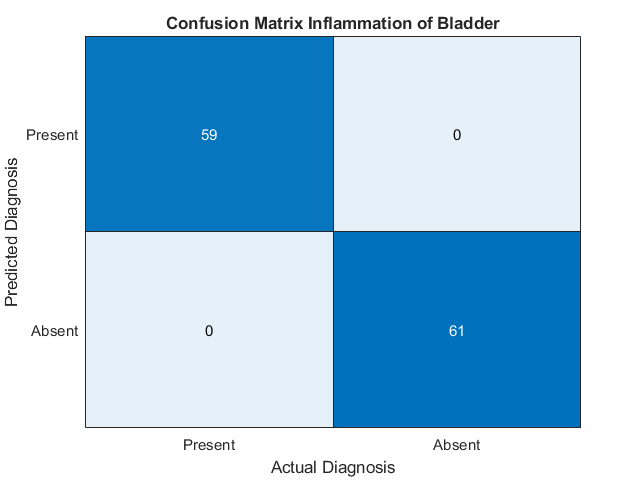

%Predict using test data
Y_pred1 = kfoldPredict(aci_Model1);

%Generate a Confusion Matrix
conMat1=confusionmat(Y,Y_pred1);
%The confusion matrix gives us a view of the rate of true positives to false negatives.
%It enables to have proper view of how effecive our model is in prediction of illness minimizing of having false negatives
conMatHeat1 = heatmap(conMat1,'Title','Confusion Matrix Inflammation of Bladder','XLabel','Actual Diagnosis','YLabel','Predicted Diagnosis',...
    'XDisplayLabels',{'Present','Absent'},'YDisplayLabels',{'Present','Absent'},'ColorbarVisible','off');

%The following functions compute the precision and F1 Score
precisionFunc = @(confusionMat) diag(confusionMat)./sum(confusionMat,2);
recallFunc = @(confusionMat) diag(confusionMat)./sum(confusionMat,1);
f1ScoresFunc = @(confusionMat) 2*(precisionFunc(confusionMat).*recallFunc(confusionMat))./(precisionFunc(confusionMat)+recallFunc(confusionMat));
meanF1Func = @(confusionMat) mean(f1ScoresFunc(confusionMat));
precision = precisionFunc(conMat1)

precision =      1
     1


recall = recallFunc(conMat1)

recall =     1.0000    0.9672
    1.0339    1.0000


f1Score = meanF1Func(conMat1)

f1Score =     1.0083    0.9917


## Performance of Nephritis of renal pelvis origin Model

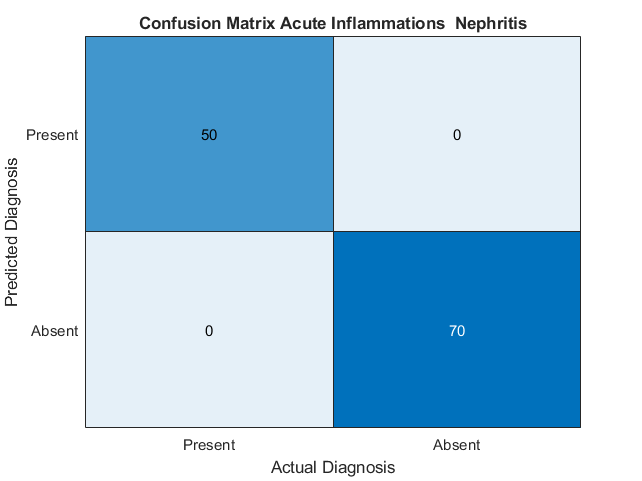

%Predict using test data
Y_pred2 = kfoldPredict(aci_Model2);

%Generate a Confusion Matrix
conMat2=confusionmat(Y2,Y_pred2);
%The confusion matrix gives us a view of the rate of true positives to false negatives.
%It enables to have proper view of how effecive our model is in prediction of illness minimizing of having false negatives
conMatHeat2 = heatmap(conMat2,'Title','Confusion Matrix Acute Inflammations  Nephritis','XLabel','Actual Diagnosis','YLabel','Predicted Diagnosis',...
    'XDisplayLabels',{'Present','Absent'},'YDisplayLabels',{'Present','Absent'},'ColorbarVisible','off');

precision = precisionFunc(conMat2)

precision =      1
     1


recall = recallFunc(conMat2)

recall =     1.0000    0.7143
    1.4000    1.0000


f1Score = meanF1Func(conMat2)

f1Score =     1.0833    0.9167
